clc;
clear;
close all;

%% Carga del modelo
load('modelo_lin.mat')

modeloLD = latmod;

Alatdir = modeloLD.A;
Blatdir = modeloLD.B;
Clatdir = modeloLD.C

Clatdir =     0.0588         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000


Dlatdir = modeloLD.D

Dlatdir =      0     0
     0     0
     0     0
     0     0
     0     0



%% Eliminacion de datos irrelevantes
Alatdir(abs(Alatdir)<1e-10)=0;
Blatdir(abs(Blatdir)<1e-10)=0;
Clatdir(abs(Clatdir)<1e-10)=0;
Dlatdir(abs(Dlatdir)<1e-10)=0;

%% Seleccion de estados
modeloLD;
Clatdir=Clatdir(4:5,:);
Dlatdir=Dlatdir(4:5,:);
Glatdir=ss(Alatdir,Blatdir,Clatdir,Dlatdir)

Glatdir =
 
  A = 
            x1       x2       x3       x4       x5
   x1   -0.875   0.8751   -16.82    9.791        0
   x2   -2.831   -16.14    3.377        0        0
   x3    1.706   0.5154   -2.783        0        0
   x4        0        1  0.05385        0        0
   x5        0        0    1.001        0        0
 
  B = 
           u1      u2
   x1       0   5.317
   x2  -156.9  -5.022
   x3   11.54  -82.27
   x4       0       0
   x5       0       0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




%% Filtros
s=tf('s');

wB1LD=8*2*pi;
A1LD=0.0003;
M1LD=0.3;

wB3LD=6*2*pi;
A3LD=0.1;
M3LD=1;

% W1=(0.5*s+0.015)/(s+0.00015);
W1LD=[(s/M1LD+wB1LD)/(s+wB1LD*A1LD) 0;
    0 (s/M1LD+wB1LD)/(s+wB1LD*A1LD)];
W2LD=[tf(1,1) 0;
    0 tf(1,1)];
W3LD=[(1+s/M3LD)/(1+(s/wB3LD)) 0;
    0 (1+s/M3LD)/(1+(s/wB3LD))];


%% Calculo del controlador
[K1,CL1,gamma1]=mixsyn(Glatdir,W1LD,W2LD,W3LD)

K1 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1    -0.01508  -1.033e-24    1.93e-26   4.463e-25   1.239e-28   6.803e-28   1.464e-26   4.661e-26   8.666e-25
   x2   1.893e-12    -0.01508  -7.254e-13  -1.307e-11   -3.58e-15  -2.209e-14   -4.28e-13  -1.582e-12  -2.533e-11
   x3   5.313e-11   8.436e-10       -37.7  -3.649e-10  -9.992e-14   -6.19e-13  -1.195e-11          32  -7.072e-10
   x4   0.0001458    0.002325  -5.589e-05       -37.7  -2.754e-07  -1.701e-06  -3.293e-05  -0.0001218          32
   x5      -189.7       -2625       68.75        1061     -0.4708       3.297       23.97       172.8        2263
   x6   1.437e+04       -1509       -5064       539.8       1.774      -194.1        8.35  -1.299e+04        1341
   x7        1892   4.092e+04      -696.2  -1.654e+04      -4.915      -24.05      -637.1       -1578  -3.528e+04
   x8   6.259e-11   9.937e-10  -2.404e-11  -4.298e-10  -1.177e-13         

gamma1 = 7.6214


%Carga del modelo
Along = longmod.A;
Blong = longmod.B;
Clong = longmod.C;
Dlong = longmod.D;

%eliminacion de datos irrelevantes
Along(abs(Along)<1e-10)=0;
Blong(abs(Blong)<1e-10)=0;
Clong(abs(Clong)<1e-10)=0;
Dlong(abs(Dlong)<1e-10)=0;

longNames = longmod.StateName;
Blong=Blong(:,1);
Clong=Clong(4,:);
Dlong=Dlong(4,1);

Glong=ss(Along,Blong,Clong,Dlong)

Glong =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1     -0.5961      0.8011      -0.871      -9.791   5.053e-05     0.01263
   x2     -0.7454      -7.581       15.72     -0.5272  -0.0009384           0
   x3       1.042      -7.427      -15.85           0           0    -0.01318
   x4           0           0           1           0           0           0
   x5    -0.05377      0.9986           0         -17           0           0
   x6       135.8       7.315           0           0    -0.08268      -5.919
 
  B = 
           u1
   x1  0.4681
   x2  -2.711
   x3  -134.1
   x4       0
   x5       0
   x6       0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




s=tf('s');

wB1=8*2*pi;
A1=0.0003;
M1=0.3;

wB3=6*2*pi;
A3=0.1;
M3=1;

% W1=(0.5*s+0.015)/(s+0.00015);

W1=(s/M1+wB1)/(s+wB1*A1);
% bodemag(1/W1,'r');
W2=tf(1,1);
% bodemag(1/W2,'g');
W3=(1+s/M3)/(1+(s/(wB3*A3)));
% bodemag(1/W3,'b');


[K,CL,gamma]=mixsyn(Glong,W1,W2,W3)

K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1    -0.01508           0           0           0           0           0           0           0
   x2   4.065e-13       -3.77   4.806e-18   5.583e-16   -5.86e-15           4   5.404e-20   1.032e-18
   x3      -180.8       23.14     -0.5944      0.5294       1.838       116.3   2.687e-05     0.01213
   x4        1047        -134     -0.7551      -6.007     0.02437      -730.9  -0.0008014    0.002903
   x5   5.177e+04       -6627      0.5623       70.39      -791.9  -3.612e+04    0.006778      0.1304
   x6    4.84e-13  -6.228e-14   5.723e-18   6.648e-16           1  -3.374e-13   6.435e-20   1.229e-18
   x7  -3.331e-10   4.286e-11    -0.05377      0.9986   4.802e-12         -17  -4.429e-17  -8.457e-16
   x8  -1.794e-10   2.309e-11       135.8       7.315   2.586e-12   1.251e-10    -0.08268      -5.919
 
  B = 
               u1
   x1           8
   x2  -4.366e-15
   x3 

gamma = 5.3206

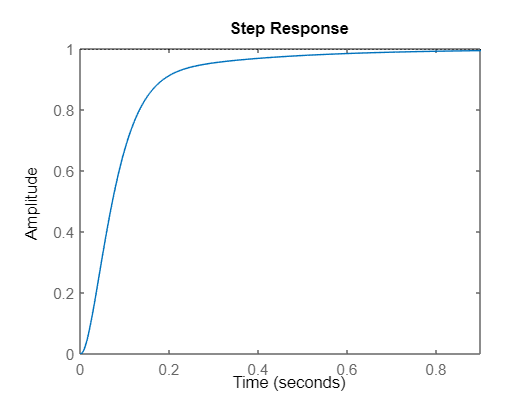


OLlong=series(K,Glong);
GCLlong=feedback(OLlong,1);
figure (1)
step(GCLlong)

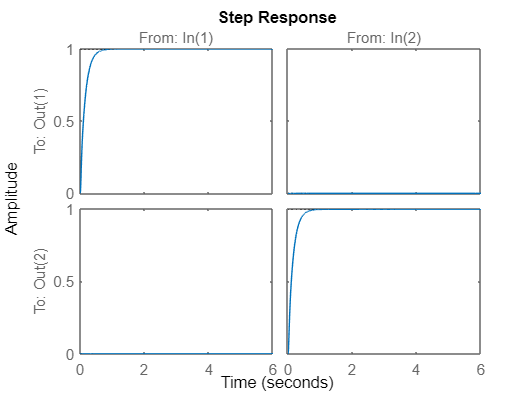


OLlatdir=series(K1,Glatdir);
I = eye(2);
GCLlatdir=feedback(OLlatdir,I);
figure (2)
step(GCLlatdir)

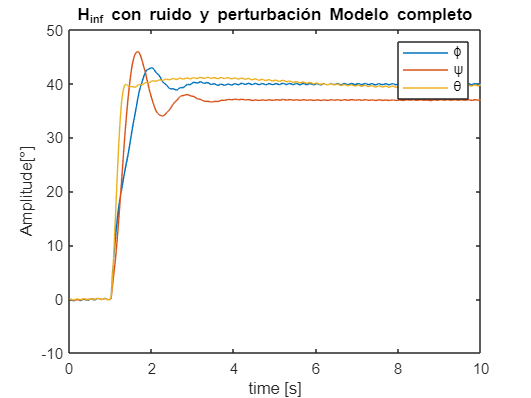

figure()
plot(out.SF.time,out.SF.signals.values)
title('H_{inf} con ruido y perturbación Modelo completo')
legend({'\phi','\psi','\theta'})
xlabel('time [s]') 
ylabel('Amplitude[°]') 